# 12. カラー画像解析

今までの演習では主にグレースケール画像を扱ってきた．最後に，カラー画像の解析をしてみよう．

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## カラー画像データの形式（RGB色空間）

カラー画像は，光の三原色である赤・緑・青からなる**RGB色空間**で表現される．画素はそれぞれの色に対応する3種類のチャネルから構成される．つまり，各画素が3値（R、G、B）を持つため，データ構造としては（正方形の画像であれば） $n\times n\times 3$次元配列となる．

n = 256;
N = n*n;

カラー画像'hibiscus'を$256\times 256$ サイズにした上で読み込む．

name = 'hibiscus';
u = load_image(name,n);
u = u/255;

カラー画像と3チャネルそれぞれを表示する．

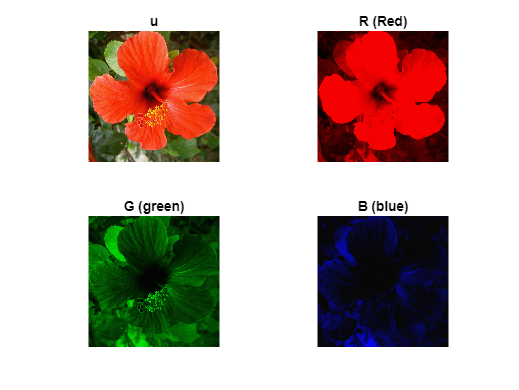

%目的の色以外のチャンネルは0で埋めることでカラー画像として表示する
R = cat(3, u(:,:,1), zeros(n), zeros(n));
G = cat(3, zeros(n), u(:,:,2), zeros(n));
B = cat(3, zeros(n), zeros(n), u(:,:,3));
figure;
% プロットする画像とキャプションをセル配列で並べることでまとめて表示できる
imageplot({u R G B}, { 'u' 'R (Red)' 'G (green)' 'B (blue)'}, 2, 2);

カラー画像からグレースケール画像を得るには，RGB成分を各画素で平均すればよい（「2. 信号・画像データの基本操作」での平均法）．

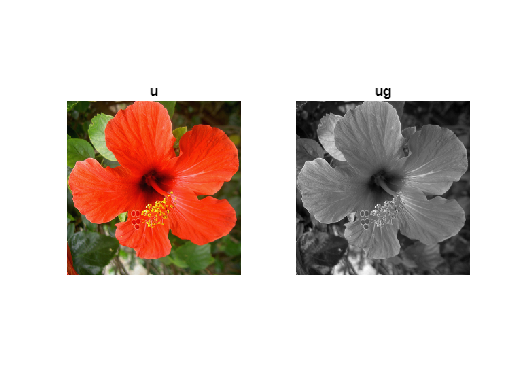

figure;
imageplot({u mean(u,3)}, {'u' 'ug'});

## 線形色空間（YUV色空間）

線形色空間は，各画素のRGB成分（3次元）に変換行列 $\mathbf{C} \in \mathbb{R}^{3\times 3}$ を適用する（＝積を計算する）ことで定義される．

典型的な線形色空間のひとつとして**YUV色空間**が知られている．ここで Y は輝度成分（luminance）， U と V は色差成分（chrominance）と呼ばれる．YUV色空間への変換は以下のように定義される．

C = [.299 .587 .114; ...
    -.14713 -.28886 .436; ...
    .615 -.51499 -.10001]';

$\mathbf{C}$ を用いてRGBをYUVへ変換する．

applymat = @(z,A) reshape( reshape(z, [n*n 3])*A, [n n 3] );
rgb2yuv  = @(z) applymat(z,C);

YUVチャンネルを表示する．

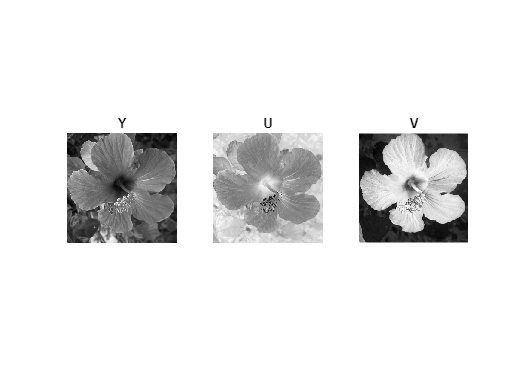

uy = rgb2yuv(u);
figure;
imageplot(uy(:,:,1), 'Y', 1,3,1);
% U, V 成分はRGBと対応していないのでグレースケールとして表示する
imageplot(uy(:,:,2), 'U', 1,3,2);
imageplot(uy(:,:,3), 'V', 1,3,3);

YUV空間で色差成分を半減させる処理を行う．

uy(:,:,2:3) = uy(:,:,2:3)/2;

上記の処理結果を元のRGB空間で表示する．RGB空間に戻すには $\mathbf{C}$ の逆行列を作用させればよい．

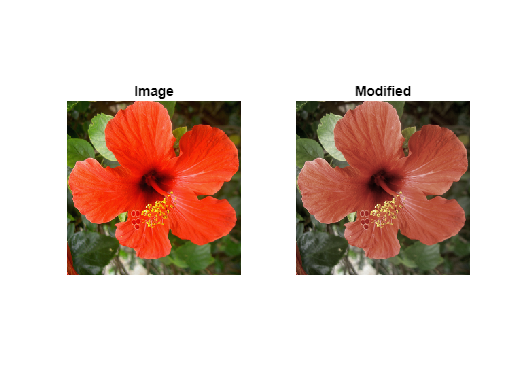

yuv2rgb = @(z) applymat(z,C^(-1));
um = yuv2rgb(uy);
figure;
imageplot(u, 'Image', 1,2,1);
imageplot(um, 'Modified', 1,2,2);

原画像に比べて色差成分を低減させているから，あせた（退色した）画像になっていることが確認できる．

## カラーヒストグラムと点群表現

カラー画像の構造を理解する上で，各成分のヒストグラムの可視化や色空間上での点群プロットが有効である．

※ 点群 (point cloud)：点の集まり

RGBの各チャネルの1次元ヒストグラムを表示する関数を定義する．

channel = @(z,i)reshape(z(:,:,i), [N 1]);

ヒストグラムを構成するビンの数を設定しヒストグラムを表示する．

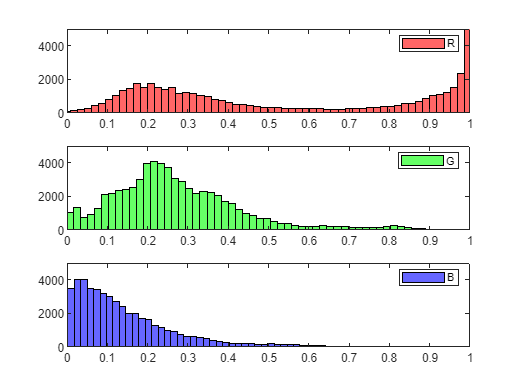

nbins = 60;
figure;
c = {'r' 'g' 'b'}; lgd = {'R' 'G' 'B'};
for i=1:3
    subplot(3,1,i);
    % Octave の場合は hist を使う
    histogram(channel(u,i), nbins, 'FaceColor',c{i});
    axis([0,1,0,5000]); % x,y軸のスケールを指定
    legend(lgd{i});
end

カラー画像の各画素は3次元空間の点とみなせるため，対応する色空間上の点群として画像をプロットできる．

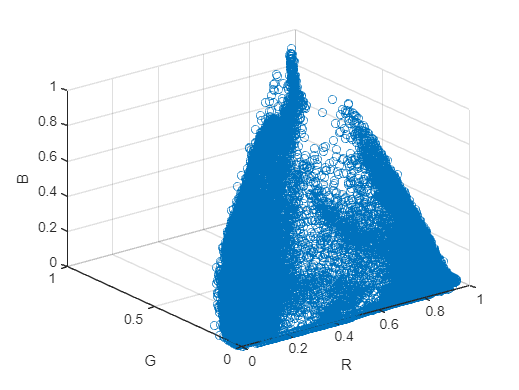

uvec = reshape(u, [N 3]);
figure;
plot3(uvec(:,1), uvec(:,2), uvec(:,3), 'o');
xlabel('R');
ylabel('G');
zlabel('B');
% x,y,z軸のスケールを指定
xlim([0,1]);
ylim([0,1]);
zlim([0,1]);
grid on; % 3Dプロットの格子表示をon

## 演習問題

**演習12-1**: カラー画像'hibiscus'を読み込み， $256\times 256$ にリスケールした上で，各チャネルに $\sigma=0.2$ のガウス性ノイズを付加した観測画像を生成する．その上で，

- 直交ウェーブレット変換（ $Jmin = 4$ ）を用いたソフトしきい値法によるノイズ除去を，RGB色空間とYUV色空間で各チャネルにそれぞれ適用し，PSNR [dB]とともに表示せよ（1枚目：原画像，2枚目：観測画像，3枚目：RGB色空間での復元画像，4枚目：YUV色空間での復元画像）．ただし，しきい値は一律で $1.2\sigma$ とせよ．近似係数はしきい値処理せず維持すること．

- 原画像・RGB復元画像・YUV復元画像それぞれのRGB色空間での点群プロットを表示せよ．

- 表示した復元画像と点群プロットを比較しながら，RGB色空間とYUV色空間でのノイズ除去結果の違いについて考察せよ．

ヒント：RGBにしろYUVにしろ，各成分ごとにウェーブレット変換・逆変換を施すこと．

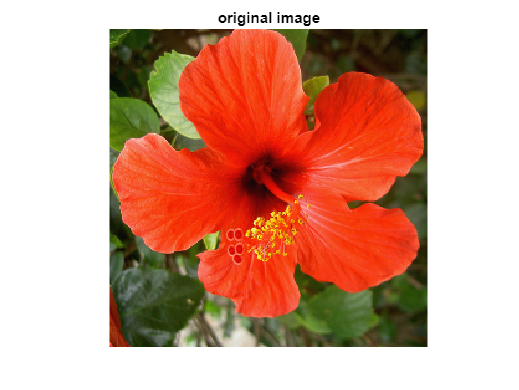

n = 256;
N = n*n;
name = 'hibiscus';
u = load_image(name,n);
u = u/255;

sigma = 0.2;
v = u + randn(n,n)*sigma;

ST = @(z,a) sign(z).*max(abs(z)-a, 0);

figure;
imageplot(u,'original image');

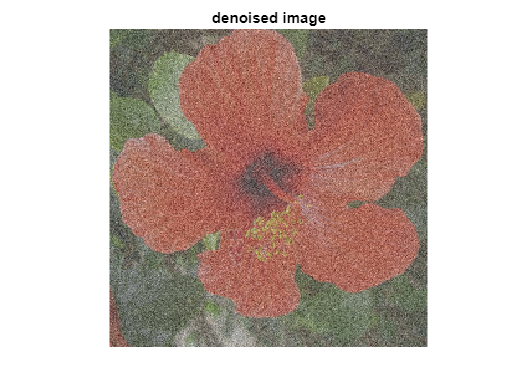

figure;
imageplot(v,'denoised image');

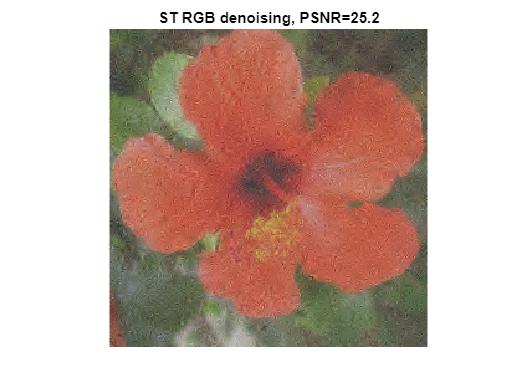


%RGB

options.ti = 0; % 直交ウェーブレット
Jmin = 4; % 最小スケール
RGBimg = zeros(n,n,3);
T = 1.2 * sigma;

for i = 1:3
    vw = perform_wavelet_transf(v(:,:,i),Jmin,+1,options); % ウェーブレット変換を施す関数

    vwT = ST(vw,T);
    vwT(1:2^Jmin,1:2^Jmin) = vw(1:2^Jmin,1:2^Jmin);
    RGBimg(:,:,i) = perform_wavelet_transf(vwT,Jmin,-1,options);
end
figure;
imageplot(RGBimg,strcat(['ST RGB denoising, PSNR=' num2str(psnr(u,RGBimg),3)]));

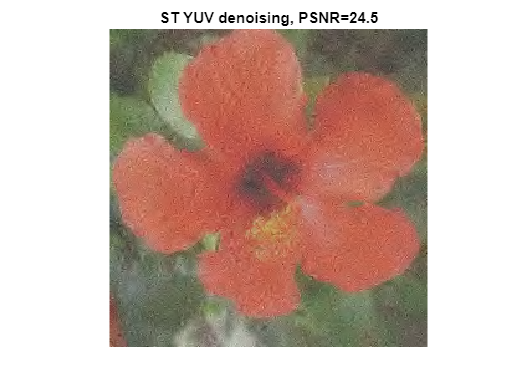


%YUV
vy = rgb2yuv(v);

options.ti = 0; % 直交ウェーブレット
Jmin = 4; % 最小スケール
YUVimg = zeros(n,n,3);
T = 1.2 * sigma;

for i = 1:3
    vw = perform_wavelet_transf(vy(:,:,i),Jmin,+1,options); % ウェーブレット変換を施す関数

    vwT = ST(vw,T);
    vwT(1:2^Jmin,1:2^Jmin) = vw(1:2^Jmin,1:2^Jmin);
    YUVimg(:,:,i) = perform_wavelet_transf(vwT,Jmin,-1,options);
end
figure;
imageplot(yuv2rgb(YUVimg),strcat(['ST YUV denoising, PSNR=' num2str(psnr(u,yuv2rgb(YUVimg)),3)]));


uvec = reshape(u, [N 3]);
figure;
plot3(uvec(:,1), uvec(:,2), uvec(:,3), 'o');
xlabel('R');
ylabel('G');
zlabel('B');
% x,y,z軸のスケールを指定
xlim([0,1]);
ylim([0,1]);
zlim([0,1]);
grid on; % 3Dプロットの格子表示をon

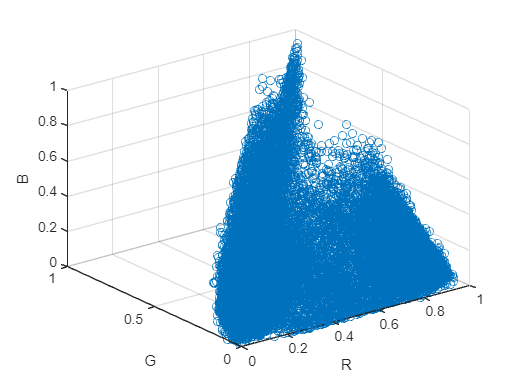


uvec = reshape(RGBimg, [N 3]);
figure;
plot3(uvec(:,1), uvec(:,2), uvec(:,3), 'o');
xlabel('R');
ylabel('G');
zlabel('B');
% x,y,z軸のスケールを指定
xlim([0,1]);
ylim([0,1]);
zlim([0,1]);
grid on; % 3Dプロットの格子表示をon

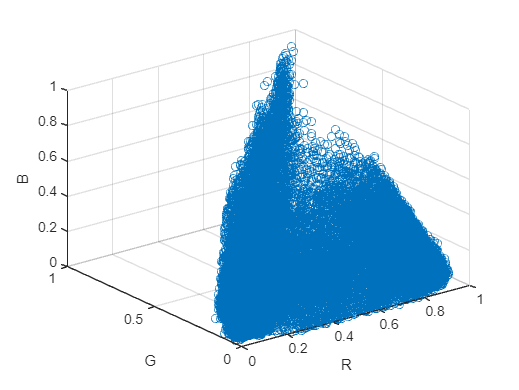


uvec = reshape(yuv2rgb(YUVimg), [N 3]);
figure;
plot3(uvec(:,1), uvec(:,2), uvec(:,3), 'o');
xlabel('R');
ylabel('G');
zlabel('B');
% x,y,z軸のスケールを指定
xlim([0,1]);
ylim([0,1]);
zlim([0,1]);
grid on; % 3Dプロットの格子表示をon

しかし、RGB色空間でのノイズ除去画像は、YUV色空間出のノイズ除去画像と比較して現画像に近い形をとっている。

これは、YUV色空間が画像の輝度をもとにとっていることが考えられる。